% First load in the data GSE1730 using import tool

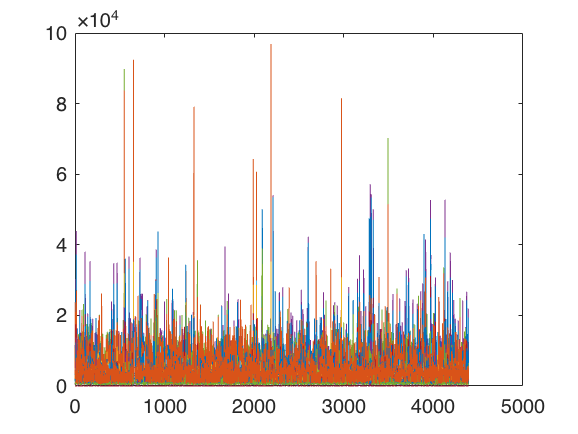

figure;
expression = GSE1(:,3:46);
expression = table2array(expression);
plot(expression)

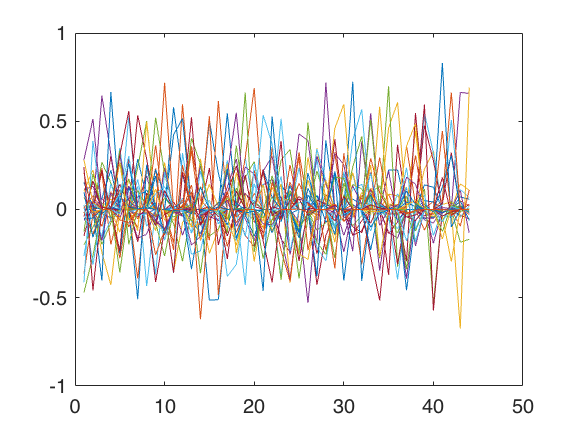


[coeff,score,latent,tsquared] = pca(expression);
figure;
plot(coeff)

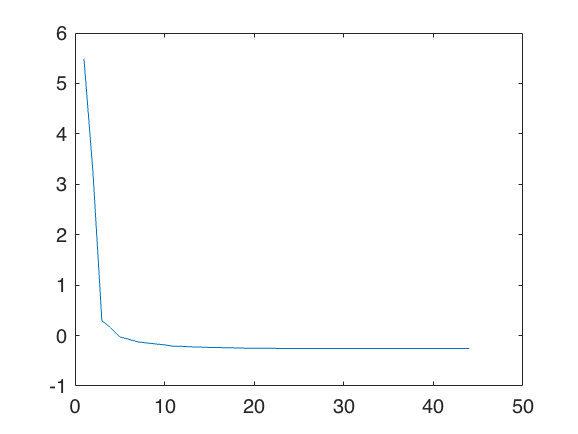

figure;
plot(normalize(latent))

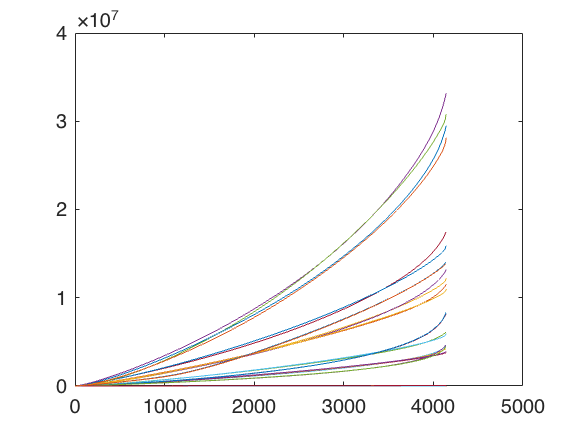

sortexpression = zeros(size(expression));
for i = 1:size(expression,2)
[~,idx] = sort(expression(:,i));
sortexpression(:,i) = expression(idx,i);
end
cumsortexpression = cumsum(sortexpression);
figure;
plot(cumsortexpression)

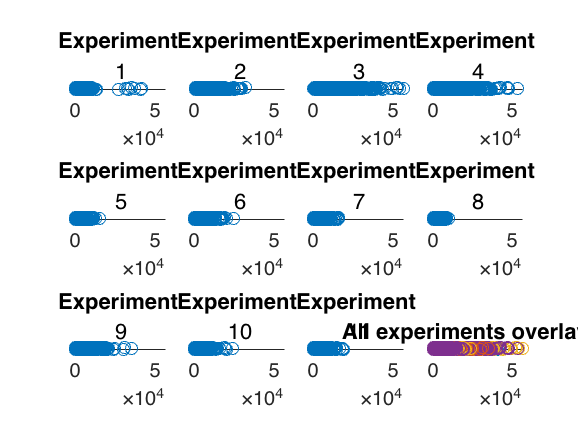

tests = zeros(size(expression,1),11);
testidx = [3 7 11 15 19 23 27 31 35 39 43];
for i = 1:length(testidx)
    tests(:,i) = expression(:,testidx(i));
end
figure;
hold on;
for i = 1:11
subplot(3,4,i);
scatter(tests(:,i),1:4666)
xlim([0 max(tests(:))])
title('Experiment ',num2str(i))
end
subplot(3,4,12);
scatter(tests,1:4666)
xlim([0 max(tests(:))])
title('All experiments overlayed')

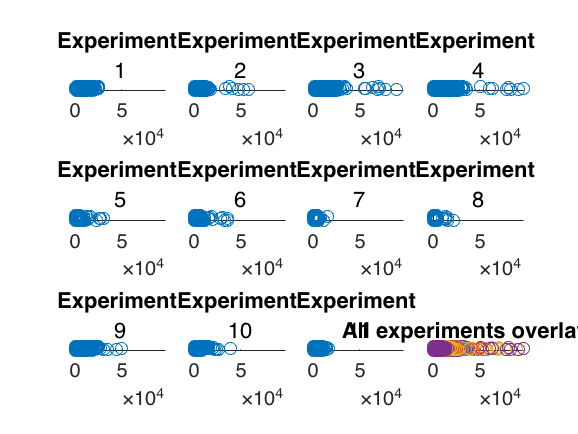

controls = zeros(size(tests));
controlidx = testidx + 1;
for i = 1:length(controlidx)
    controls(:,i) = expression(:,controlidx(i));
end
figure;
hold on;
for i = 1:11
subplot(3,4,i);
scatter(controls(:,i),1:4666)
title('Experiment ',num2str(i))
xlim([0 max(controls(:))])
end
subplot(3,4,12);
scatter(controls,1:4666)
xlim([0 max(controls(:))])
title('All experiments overlayed')

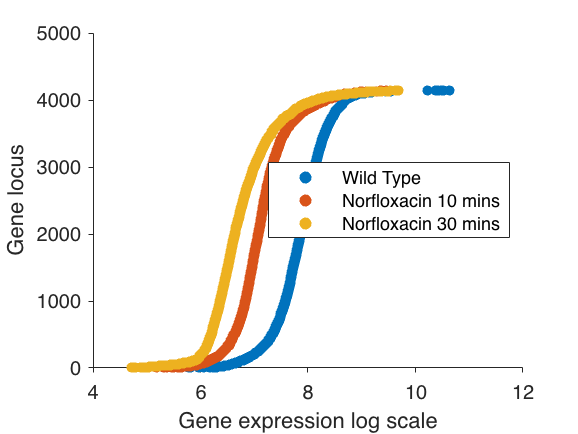

wtData = tests(:,1);
wtControl = controls(:,1);
sortwtData = sort(wtData);
sortwtControl = sort(wtControl);
figure;
hold on;
scatter(log(sortwtData),1:length(sortwtData),25,"filled")

norf10Data = tests(:,5);
sortNorf10Data = sort(norf10Data);
scatter(log(sortNorf10Data),1:length(sortNorf10Data),25,"filled")

norf30Data = tests(:,7);
sortNorf30Data = sort(norf30Data);
scatter(log(sortNorf30Data),1:length(sortNorf30Data),25,"filled")

legend('Wild Type', 'Norfloxacin 10 mins','Norfloxacin 30 mins',Location='east')
set(gca, 'TickDir', 'out', 'Box', 'off')
ylabel('Gene locus')
xlabel('Gene expression log scale')

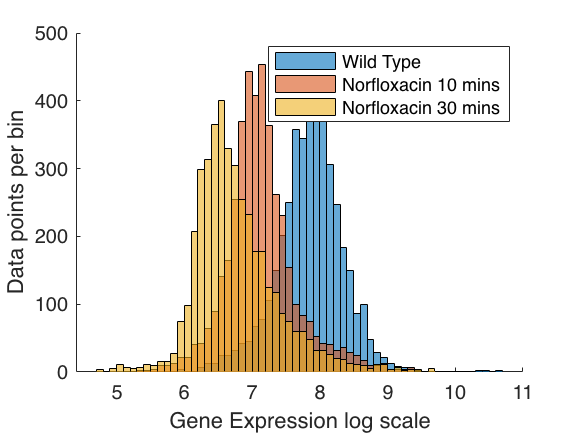

figure;
hold on;
histogram(log(wtData));
histogram(log(norf10Data));
histogram(log(norf30Data));
legend('Wild Type','Norfloxacin 10 mins','Norfloxacin 30 mins')
xlabel('Gene Expression log scale')
ylabel('Data points per bin')